# Constant forcing

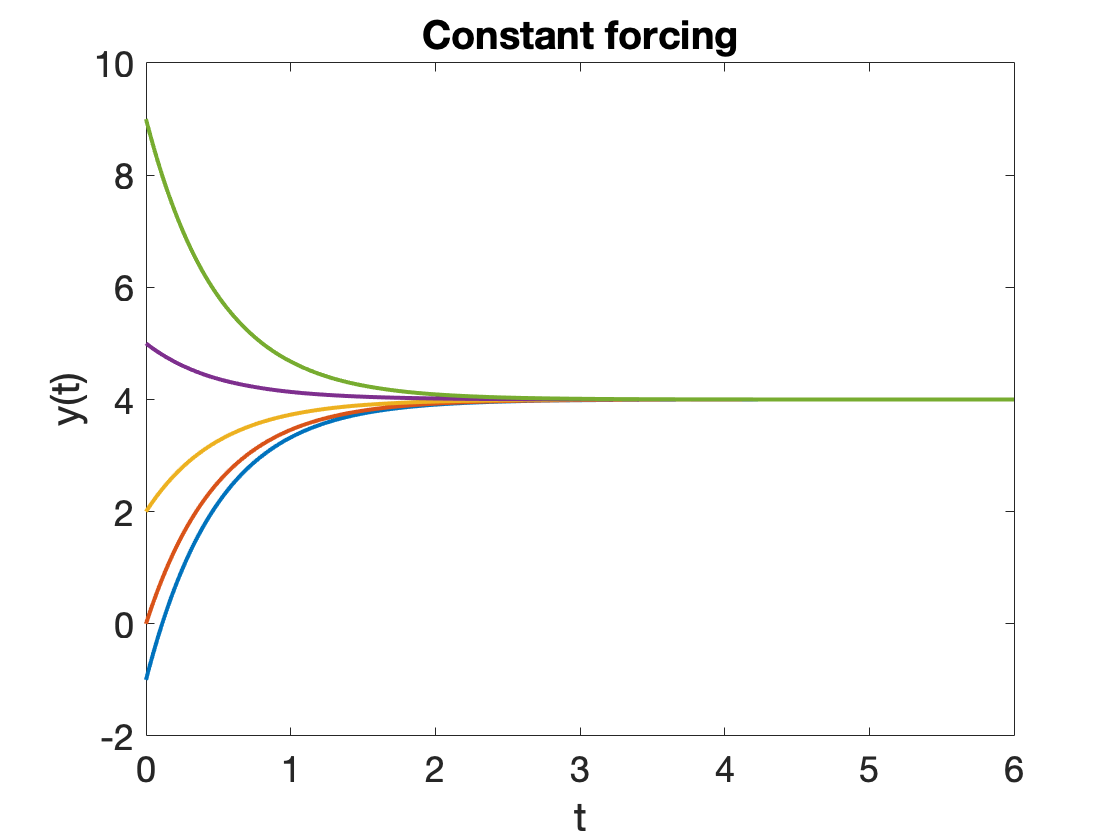


dydt = @(t,y) 8-2*y;
t = linspace(0,6,1000);
clf
for y0 = [-1 0 2 5 9]
    [t,y] = ode45(dydt,t,y0);
    plot(t,y)
    hold on
end
xlabel('t'), ylabel('y(t)')
title('Constant forcing')

## Step forcing

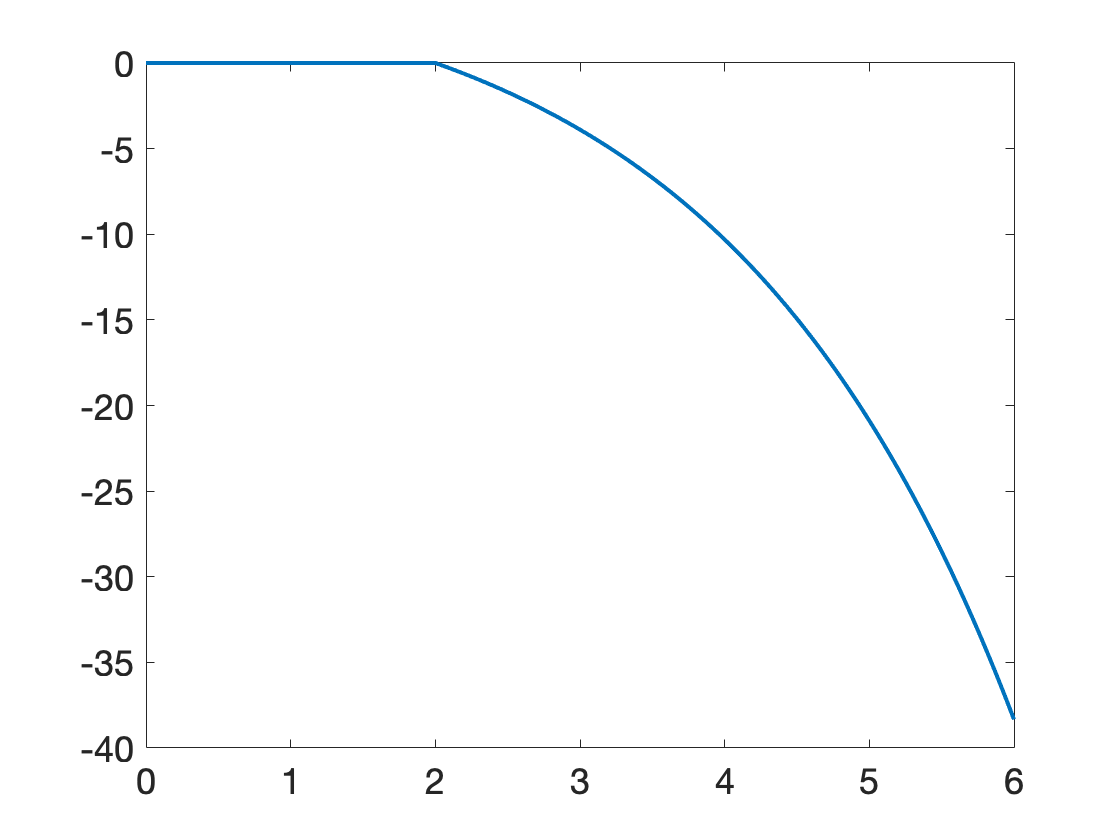

step = @(t) double(t>=0);
t = linspace(0,6,1000);
dydt = @(t,y) 0.5*y - 3*step(t-2);
[t,y] = ode45(dydt,t,0);
clf, plot(t,y)